# Modelo de un robot que toma y deja piezas

# Clase Piezas y método $PegarEn()$

Dificultad: Normal (Básico)

## General

- Se pretende realizar una estación donde el robot tome y deje piezas de la estación.

- El sistema se compone del robot, una pinza y una carga. En dicha carga es donde se va a tomar o dejar piezas de la estación.

- Si una pieza está en un icono asociado a la base no se mueve, pero si está asociado al icono de la carga, se va a mover con el robot.

- Va a haber un cambio de elementos entre el icono de la carga y el de la base. Este cambio no se va a apreciar mientras el robot no se mueva, porque la posición de la pieza respecto de la referencia global permanece constante durante el cambio.

- La clase $Pieza$ tiene un método $PegarEn()$ que facilita el trabajo. Este método copia las propiedades de un icono en otro, modificando la posición relativa al eje base para que la posición absoluta de la pieza no varíe.

## Crear la estación y sus puntos de trabajo para la cinemática inversa

### Estación del sistema

- Se dispone de un robot con pinza y carga. En la carga al inicio hay un lapiz.

- Piezas estáticas asociadas a la base. Entre ellas hay un icono LapExt que al inicio está vacío ($Null$, esfera muy pequeña). En este icono es donde se va a dejar el lapiz durante la acción de dejar lápiz desde la carga.

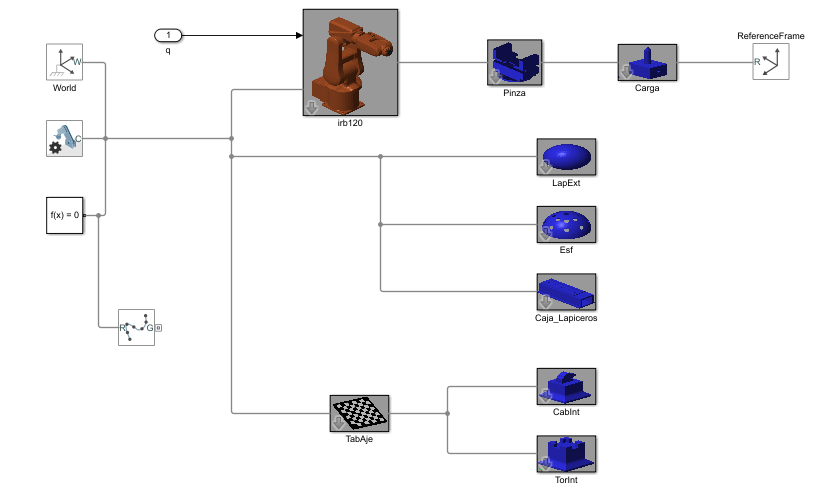


clear all
close all
clc


deg= pi/180;
Estacion= 'C12S1_irb120_Ajedrez.slx';

% Se inicia la clase con el robot con el interface de simulink
% VER VERSIÓN SIMULINK
% Variables de simulink

% Posición inicial del robot y del rastreador
% Estas variables van a ser usadas por los objetos Cin. 
% No deben modificarse en el programa 
q0_= zeros(1,6);
pose_= randn(3,3)*1e-3;

% Posición de la base del robot [[x,y,z]mm,[Rz,Ry,Rx]rad]
baseRobot= [[0,0,0]*1e-3, [0,0,0]*deg];


% Tool load y wobj Se genera una variable estructura de nombre tool1

% Icono variable
Pinza= Pieza('Pinza_Completa');
Pinza.Base([[0,0,0]*1e-3, [90,0,0]*deg]);
Pinza.Tcp(([[0,0,70]*1e-3, [0,0,0]*deg]));
Pinza.Color([0.4,0,0.4,0.7]);

% Objeto de trabajo
Carga= Pieza('Lapiz');
Carga.Tcp([[0,0,148]*1e-3, [0,0,0]*deg]);
Carga.Color([0,0.4,0.4,0.7]);

% Objeto de trabajo
Esf= Pieza('Esfera');
Esf.Base([[0,-350,0]*1e-3, [0,0,0]*deg]);
Esf.Color([0,0.3,0.8,0.7]);

% Objeto de trabajo fijo ya que contiene dos ficheros stl.
% No se va a usar su nombre, luego lo ponemos como Null
TabAje= Pieza();
TabAje.Base([[175,-200, 150]*1e-3, [0,0,0]*deg]);
% La salida se ajusta a la primera casilla 
TabAje.Tcp([[25,25,7]*1e-3,[0,0,0]*deg]);
TabAje.Color([0.3, 0.8, 0.2, 0.7]);

% Objeto de trabajo
CajLap= Pieza('SoporteLapiceros');
CajLap.Base([[0, 350, 0]*1e-3, [0, 0, 0]*deg]);
CajLap.Color([0.3,0.2,0.7,0.7]);

% Icono variable
% Load vacio para poner el lapiz fuera de la carga
% Se coloca Null que es una esfera pequeña
pExt1= Pieza('Null');



% Cargas para el robot
pTab1= Pieza('Torre');
Px= 1; Py= 1;
pTab1.Base([[50*Px, 50*Py, 0]*1e-3, [0,0,0]*deg])
pTab1.Color([1,1,1,1]);

% Carga del robot
pTab2= Pieza('Caballo');
Px= 3; Py= 5;
pTab2.Base([[50*Px, 50*Py, 0]*1e-3, [0,0,0]*deg])
pTab2.Color([0,0,0,1]);


## Importar el fichero de Multi-body con RigidBody 

- Se importa el fichero SimScape de Simulink al objeto RigidBody de la librería de robótica.

- Se determina los objetos que corresponden con la pinza y la carga.

robot= importrobot(Estacion);

--------------------
Robot: (10 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  
   2        Body02        Joint02       revolute            Body01(1)   Body03(3)  
   3        Body03        Joint03       revolute            Body02(2)   Body04(4)  
   4        Body04        Joint04       revolute            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06       revolute            Body05(5)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   Body08(8)  
   8        Body08        Joint08          fixed            Body07(7)   Body09(9)  
   9        Body09        Joint09          fixed            Body08(8)   Body10(10)  
  10        Body10      

robot.showdetails
% Puntos de interes para cinemática inversa

% para Estacion= 'Estacion_Ejemplo_abbIrb120.slx'
TcpPinza= 'Body09';
TcpCarga= 'Body10';

% Ver la estación construida
open_system(Estacion)


## Generar el objeto $Cin()$ con el robot RigidBody, el equivalente MultiBody y la herramienta desea.

% Posición inicial del robot y del rastreador
q0= [0,0,0,0,0,0];

rob= Cin(robot, Estacion, TcpCarga, q0);

Herramienta: Body10
Simulación. Ts= 0.100 m/s


## Diagrama y simulación inicial

## 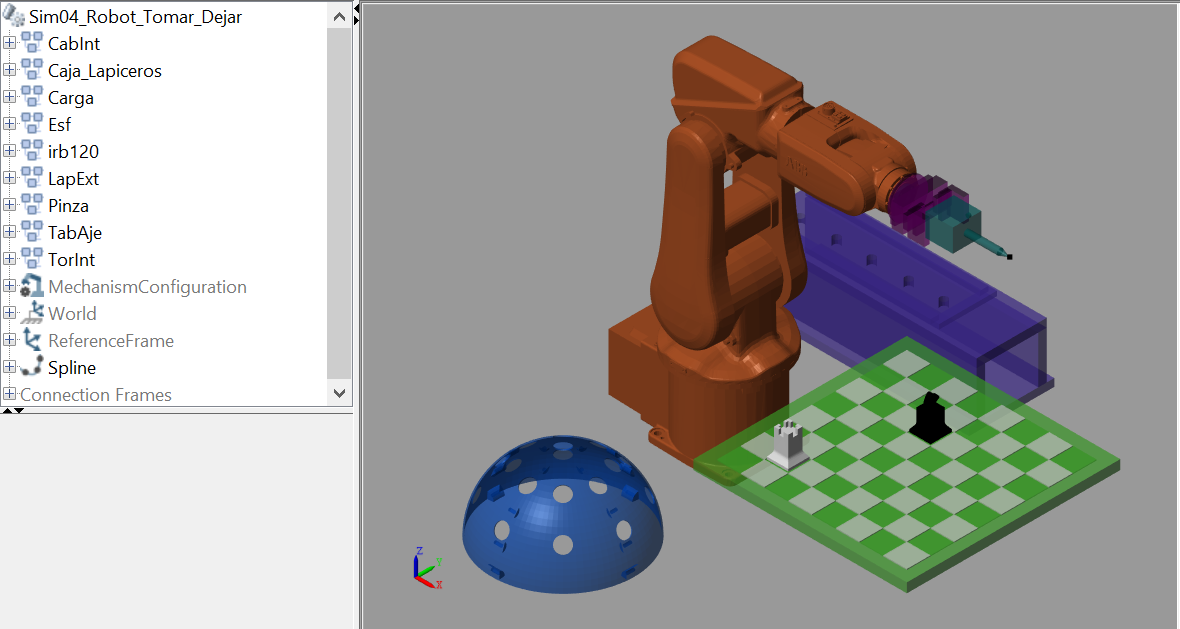

## Dejar y Tomar la herramienta (Lápiz) en una posición y volver a por ella.

## Método $Pieza.PegarEn(load_1,load_2,ref_1,ref_2)$

- Copia las propiedades del objeto $load_2$ en $load_1$.

- Los argumentos $ref_1$ y $ref_2$ son los matrices homogéneas (o $[x,y,z,R_z,R_y,R_x]$) de las referencias a $load_1$ y $load_2$ respectivamente. Si un objeto tiene como referencia la referencia global se puede poner por defecto $[]$.

- El método modifica la posición de la pieza en $load_1$ de forma que la pieza que había en $load_2$ y ahora está en $load_1$ no cambie de posición aparente. 

- El icono $load_2$ se pone como objeto nulo, es decir, esfera de radio muy pequeño. 

### Dejar la carga en el lápiz de la base de la esfera

- Se deja el icono carga (Carga) en una posición relativa a la esfera (en el icono LapExt)

- Se mueve el robot pero la pieza lápiz permanece en su posición.


rob.Tool(TcpCarga);
qinit= [0,0,0,0,90,0]*deg;
rob.MoveAbsJ(qinit);
punto= [[0,0,300]*1e-3,[0,0,-180]*deg];

rob.MoveJ(punto, Esf);
punto= [[0,0,90]*1e-3,[0,0,-180]*deg];

rob.MoveL(punto, Esf);

% Cambio de tcp del robot y miro la posición en esa tcp donde está la pieza
% La herramienta se deja en la posición actual del TCP del tool1
rob.Tool(TcpPinza);

% Pegar en pExt1 la Carga, pExt1 depende del eje principal y la carga de
% la posición de la pinza

PegarEn(pExt1, Carga, [], rob);

% Muevo al inicio
rob.MoveAbsJ(qinit);


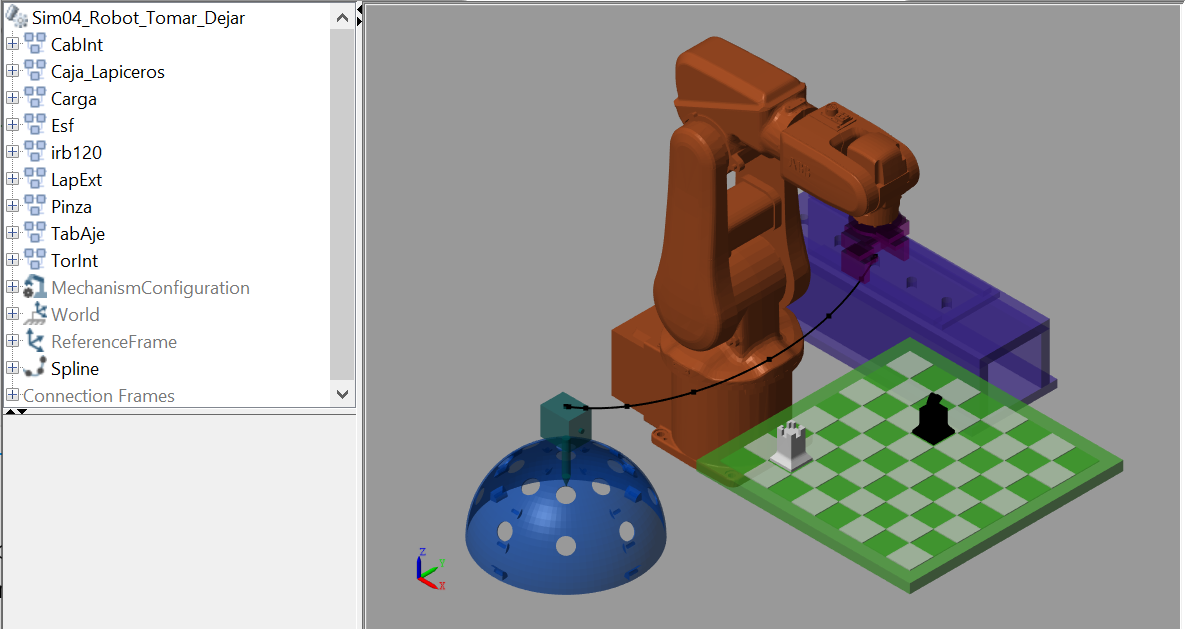

### Tomar la carga (Lápiz)

- El robot va a la base de la pieza.

- Se intercambia cambia la pieza del icono exterior a la carga del robot.

rob.MoveJ(pExt1.base);
% Pegar en la carga el LapExt. La carga depende de la posición de la pinza
% y el LapExt de la base

PegarEn(Carga, pExt1, rob, []);
rob.Tool(TcpCarga);

punto= [[0,0,300]*1e-3,[0,0,-180]*deg];
rob.MoveL(punto,Esf);
rob.MoveAbsJ(qinit);


## Tomar y dejar la torre dentro del tablero

### Tomar la torre. Ir a donde está situada

- El robot va por encima de la torre, teniendo en cuenta la posición base de la torre.

### Ir al punto


% Herramienta Pinza
rob.Tool(TcpPinza);
% Posición actual de la pieza
% Nos situamos zbase por encima de la pieza que deseamos tomar.
qinit= [0,0,0,0,90,0]*deg;
rob.MoveAbsJ(qinit);
punto= [[0,0,50]*1e-3,[0,0,-180]*deg];
% Vamos a 50 por encima de la pieza. La pieza está en el tablero y del
% tablero a la posición de la torre

%rob.MoveJ(punto, TabAje.Htcp*pTab1.Hbase);
rob.MoveJ(punto, Prod(TabAje, pTab1));


### Tomar la pieza

- Se intercambia información entre $load_1$ (carga robot) y $load_2$ (torre).

- La posición se ajusta para que la pieza no se mueva.



% Pegar en la Carga la torre. La carga depende de la posición de la pinza y
% la torre del tablero
%PegarEn(Carga, pTab1, rob.Pose, TabAje.Htcp);
PegarEn(Carga, pTab1, rob, TabAje);
rob.MoveAbsJ(qinit);

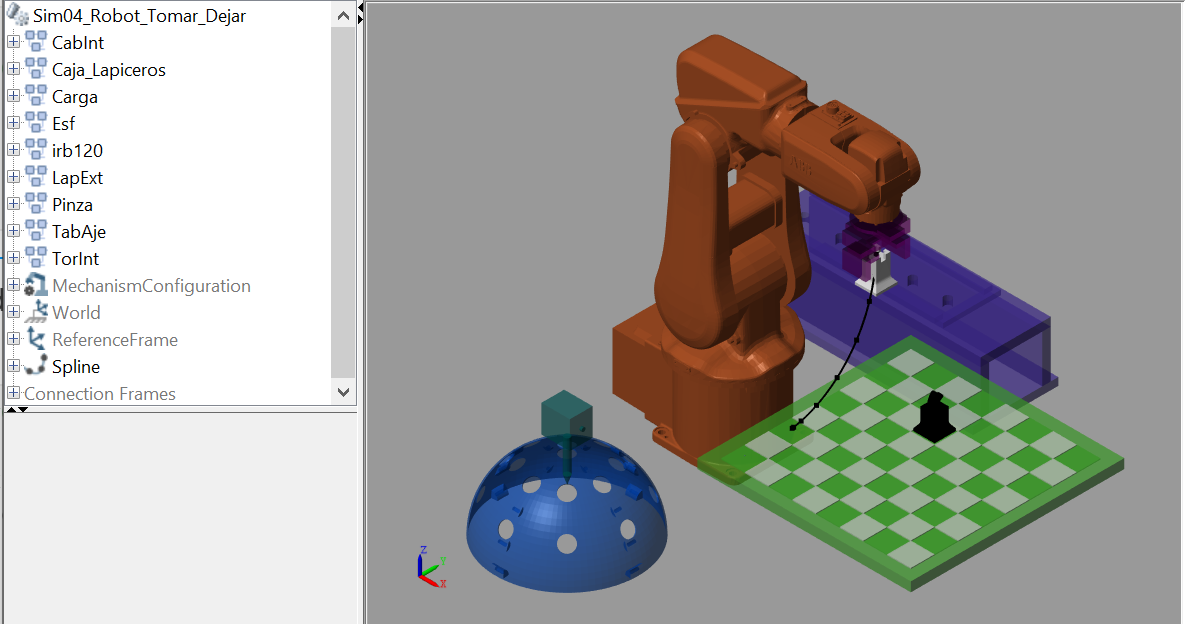

### Dejar la pieza dentro del tablero

- El robot deja la carga en otra posición relativa al tablero de ajedrez.

%rob.Tool(TcpCarga)
Px= 5; Py= 5;
punto= [[50*Px, 50*Py, 50]*1e-3, [0,0,180]*deg];
% Nos vamos a una posición relativa del tablero
rob.MoveJ(punto, TabAje.Htcp);

%PegarEn(pTab1, Carga, TabAje.Htcp, rob.Pose);
PegarEn(pTab1, Carga, TabAje, rob);
rob.MoveAbsJ(qinit);

###